# Analise das distribuições no disco rotor

### Descida axial

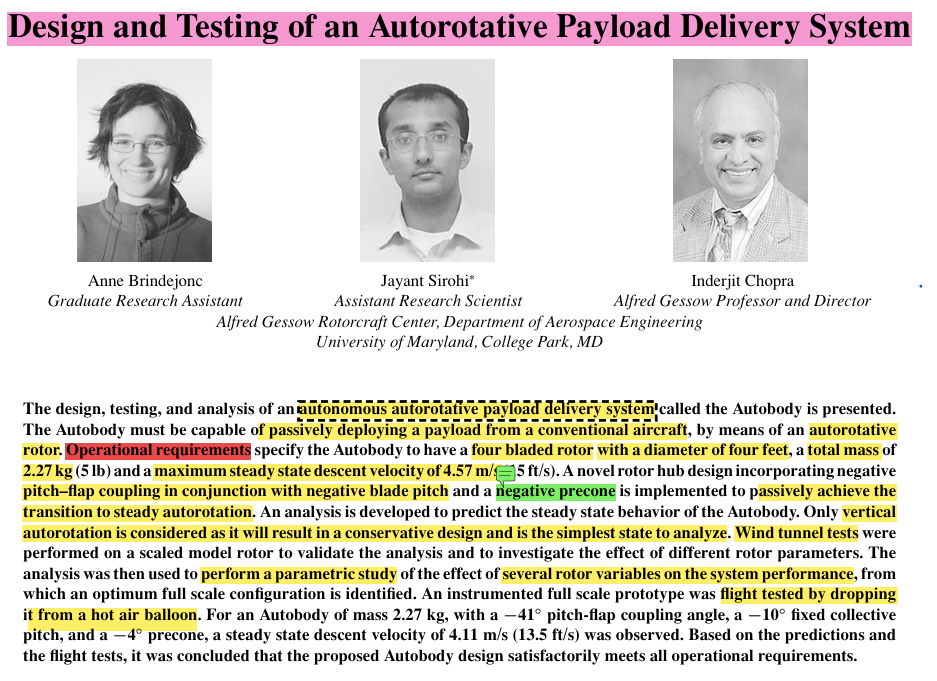

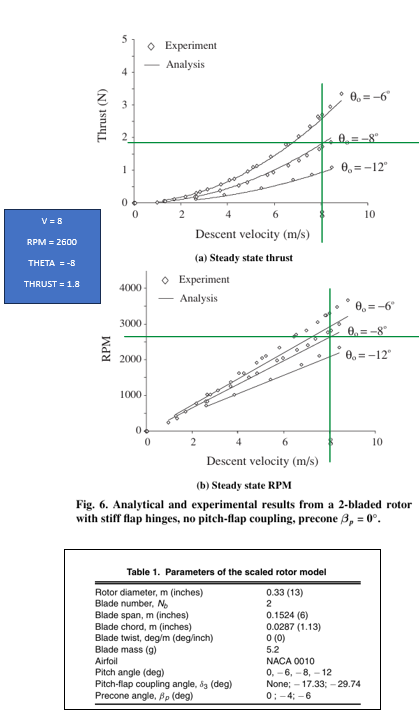

clc
clear
close all

#### Características do rotor

disk_radius = 0.33;
Nb = 2;
Span = 0.1524;
RootBladeDistance = disk_radius/2 - 0.1524;
twist_rate = 0;
chord = 0.0287;
disk_area = pi * ((disk_radius/2)^2);

**outros**

density = 1.225;

mass_payload = 0;
vehicle_position = [0; 0; 0];
vehicle_orientation = [0; 0; 0];

#### Experimental Data

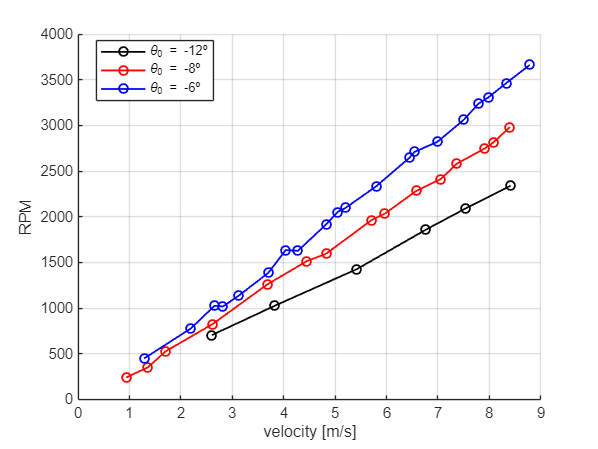

RPMS = readmatrix("./studies/rotor_analysis/sim_B/rpm.xlsx");
figure()
hold on
plot(RPMS(:, 1), RPMS(:, 2), 'ko-', 'DisplayName', '\theta_0 = -12º', 'LineWidth',1.2)
plot(RPMS(:, 3), RPMS(:, 4), 'ro-', 'DisplayName', '\theta_0 = -8º', 'LineWidth',1.2)
plot(RPMS(:, 5), RPMS(:, 6), 'bo-', 'DisplayName', '\theta_0 = -6º', 'LineWidth',1.2)
hold off
grid on
legend('Location','best')
xlabel("velocity [m/s]")
ylabel("RPM")

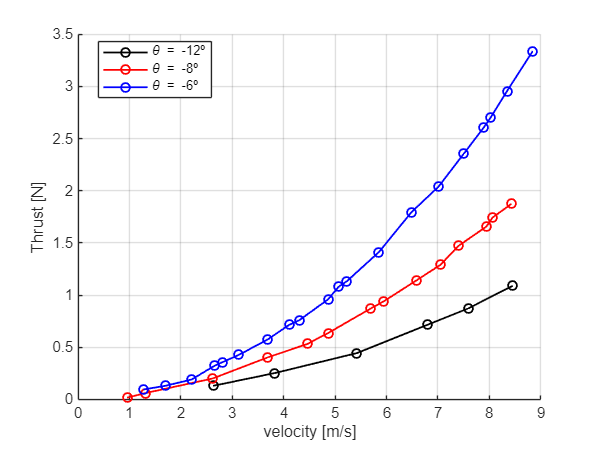


THRUST = readmatrix("./studies/rotor_analysis/sim_B/thrust.xlsx");
figure()
hold on
plot(THRUST(:, 1), THRUST(:, 2), 'ko-', 'DisplayName', '\theta = -12º', 'LineWidth',1.2)
plot(THRUST(:, 3), THRUST(:, 4), 'ro-', 'DisplayName', '\theta = -8º', 'LineWidth',1.2)
plot(THRUST(:, 5), THRUST(:, 6), 'bo-', 'DisplayName', '\theta = -6º', 'LineWidth',1.2)
hold off
grid on
legend('Location','best')
xlabel("velocity [m/s]")
ylabel("Thrust [N]")

valid_idx = ~isnan(RPMS(:,1)) & ~isnan(RPMS(:,2));
RPMS_clean = RPMS(valid_idx, :);
f_r_v_1 = fit(RPMS_clean(:,1), RPMS_clean(:,2), 'smoothingspline');

valid_idx = ~isnan(RPMS(:,3)) & ~isnan(RPMS(:,4));
RPMS_clean = RPMS(valid_idx, :);
f_r_v_2 = fit(RPMS_clean(:,3), RPMS_clean(:,4), 'smoothingspline');

valid_idx = ~isnan(RPMS(:,5)) & ~isnan(RPMS(:,6));
RPMS_clean = RPMS(valid_idx, :);
f_r_v_3 = fit(RPMS_clean(:,5), RPMS_clean(:,6), 'smoothingspline');

valid_idx = ~isnan(THRUST(:,1)) & ~isnan(THRUST(:,2));
THRUST_clean = THRUST(valid_idx, :);
f_t_v_1 = fit(THRUST_clean(:,1), THRUST_clean(:,2), 'smoothingspline');

valid_idx = ~isnan(THRUST(:,3)) & ~isnan(THRUST(:,4));
THRUST_clean = THRUST(valid_idx, :);
f_t_v_2 = fit(THRUST_clean(:,3), THRUST_clean(:,4), 'smoothingspline');

valid_idx = ~isnan(THRUST(:,5)) & ~isnan(THRUST(:,6));
THRUST_clean = THRUST(valid_idx, :);
f_t_v_3 = fit(THRUST_clean(:,5), THRUST_clean(:,6), 'smoothingspline');


## Tabela para valores experimentais

theta_0 = [-6, -8, -12];
v = [2, 4, 8];

azimutal_points = 25;
No_elements = 100;

blade_integrator = 'Trapezoidal'; %'Rectangle' | 'Simpson' | 'Trapezoidal' | 'Boole'

for p = 1:3
    for j = 1:3
        if theta_0(p) == -12
            RPM = f_r_v_1(v(j));
            T = f_t_v_1(v(j));
        elseif theta_0(p) == -8
            RPM = f_r_v_2(v(j));
            T = f_t_v_2(v(j));
        elseif theta_0(p) == -6
            RPM = f_r_v_3(v(j));
            T = f_t_v_3(v(j));
        end
        
        theta = theta_0(p);
              
        vehicle_velocity = [0; 0; -v(j)];
    
        vh = sqrt(T/(2*density*disk_area));
        Vc = vehicle_velocity(3);
    
        if Vc/vh <= -2 
            mode = "windmill break state";            
        else
            mode = "vortex ring";
        end


        induced_velocity = vh * (-Vc/(2*vh) - sqrt((Vc/(2*vh))^2 - 1));
               
        

        sim_init_rotor_simulation
        [F_rotor, T_rotor, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
       
        fprintf("[%s] theta = %.0f | v = %.2f | rpm = %.2f | thrust = %.4f | vi = %.4f \n", mode, theta, vehicle_velocity(3), RPM, T, induced_velocity)        
        fprintf("\tF_rotor = %.4f | %.4f |  %.4f \n", F_rotor)
        fprintf("\tT_rotor = %.4f | %.4f |  %.4f\n", T_rotor)
        fprintf("\tError: %.1f%% \n\n\n", abs(T-F_rotor(3))/T * 100)

        % para gerar a tabela de resultados em formato latex
        % fprintf(" %.0f & %.0f & %.2f & %.3f & %.3f & %.3f & %.1f \\\\\n", theta, vehicle_velocity(3), RPM, T, induced_velocity, F_rotor(3), abs(T-F_rotor(3))/T * 100)

    end
end

[windmill break state] theta = -6 | v = -2.00 | rpm = 700.59 | thrust = 0.1619 | vi = 0.5232 


	F_rotor = -0.0000 | -0.0000 |  0.1140 


	T_rotor = 0.0000 | -0.0000 |  0.0007


	Error: 29.6% 




[windmill break state] theta = -6 | v = -4.00 | rpm = 1573.23 | thrust = 0.6746 | vi = 1.1163 


	F_rotor = -0.0000 | -0.0000 |  0.5420 


	T_rotor = 0.0000 | -0.0000 |  0.0047


	Error: 19.7% 




[windmill break state] theta = -6 | v = -8.00 | rpm = 3322.39 | thrust = 2.6872 | vi = 2.2178 


	F_rotor = -0.0000 | -0.0000 |  2.2445 


	T_rotor = 0.0000 | 0.0000 |  0.0189


	Error: 16.5% 




[windmill break state] theta = -8 | v = -2.00 | rpm = 619.54 | thrust = 0.1274 | vi = 0.3739 


	F_rotor = -0.0000 | 0.0000 |  0.0777 


	T_rotor = 0.0000 | 0.0000 |  0.0006


	Error: 39.0% 




[windmill break state] theta = -8 | v = -4.00 | rpm = 1370.03 | thrust = 0.4514 | vi = 0.6414 


	F_rotor = -0.0000 | 0.0000 |  0.3540 


	T_rotor = 0.0000 | -0.0000 |  0.0040


	Error: 21.6% 




[windmill break state] theta = -8 | v = -8.00 | rpm = 2791.17 | thrust = 1.7008 | vi = 1.1922 


	F_rotor = -0.0000 | 0.0000 |  1.4014 


	T_rotor = 0.0000 | -0.0000 |  0.0155


	Error: 17.6% 




[windmill break state] theta = -12 | v = -2.00 | rpm = 550.48 | thrust = 0.0670 | vi = 0.1751 


	F_rotor = -0.0000 | -0.0000 |  0.0379 


	T_rotor = 0.0000 | -0.0000 |  0.0003


	Error: 43.4% 




[windmill break state] theta = -12 | v = -4.00 | rpm = 1063.95 | thrust = 0.2691 | vi = 0.3521 


	F_rotor = -0.0000 | -0.0000 |  0.1882 


	T_rotor = 0.0000 | -0.0000 |  0.0031


	Error: 30.1% 




[windmill break state] theta = -12 | v = -8.00 | rpm = 2224.33 | thrust = 0.9759 | vi = 0.6321 


	F_rotor = -0.0000 | 0.0000 |  0.7298 


	T_rotor = 0.0000 | -0.0000 |  0.0110


	Error: 25.2% 




v = 1:1:8;
theta_0 = [-6 -8 -12];

azimutal_points = 25;
No_elements = 100;
blade_integrator = 'Trapezoidal';

for p=1:length(theta_0)
    for j=1:length(v)

        if theta_0(p) == -12
            RPM = f_r_v_1(v(j));
            T = f_t_v_1(v(j));
        elseif theta_0(p) == -8
            RPM = f_r_v_2(v(j));
            T = f_t_v_2(v(j));
        elseif theta_0(p) == -6
            RPM = f_r_v_3(v(j));
            T = f_t_v_3(v(j));
        end
        
        theta = theta_0(p);
              
        vehicle_velocity = [0; 0; -v(j)];
    
        vh = sqrt(T/(2*density*disk_area));
        Vc = vehicle_velocity(3);
    
        if Vc/vh <= -2 
            mode = "windmill break state";            
        else
            mode = "vortex ring";
        end


        induced_velocity = vh * (-Vc/(2*vh) - sqrt((Vc/(2*vh))^2 - 1));

        sim_init_rotor_simulation
        [F_rotor, ~, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
    
        T_vec(p, j) = F_rotor(3);
    end
end

                 Span: 0.1524
    RootBladeDistance: 0.0126
          No_elements: 100
                theta: -6
           twist_rate: 0
                chord: 0.0287
     prandtlTipLosses: 1
         airfoil_name: 'naca0010'
         airfoil_data: [1×149 struct]
                   tc: 0.1200
                   AR: 5.3101
      fixed_positions: [0 180]
            thickness: 0.0034
                   dy: 0.0015
                   dA: 4.3739e-05
              pos_sec: [3×101 double]
                 mass: 0.0030

    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6    -6 

Error using cfit/subsref>iParenthesesReference (line 45)
Cannot evaluate CFIT model for some reason.

Error in indexing (line 15)
        out = iParenthesesReference( obj, currsubs );

Error in 


figure()
hold on;
grid on;
% Define colors in RGB
colors = {'b', 'r', 'k'}; % Blue, Red, Black
legend('Location', 'northwestoutside');

THRUST = readmatrix("./studies/rotor_analysis/sim_B/thrust.xlsx");

% Plot with correct color
h1 = plot(v, T_vec(1, :), '^-', 'LineWidth', 1.2, 'Color', colors{1}, 'HandleVisibility', 'off');
h2 = plot(v, T_vec(2, :), '^-', 'LineWidth', 1.2, 'Color', colors{2}, 'HandleVisibility', 'off');
h3 = plot(v, T_vec(3, :), '^-', 'LineWidth', 1.2, 'Color', colors{3}, 'HandleVisibility', 'off');

h4 = plot(THRUST(:, 5), THRUST(:, 6), 'bo-', 'LineWidth',1.2, 'HandleVisibility', 'off');
h5 = plot(THRUST(:, 3), THRUST(:, 4), 'ro-', 'LineWidth',1.2, 'HandleVisibility', 'off');
h6 = plot(THRUST(:, 1), THRUST(:, 2), 'ko-', 'LineWidth',1.2, 'HandleVisibility', 'off');

% Criar marcadores invisíveis para representar a fonte (Model e Paper)
p1 = plot(NaN, NaN, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8, 'DisplayName', 'Paper'); % Círculo preto
p2 = plot(NaN, NaN, 'k^', 'MarkerFaceColor', 'k', 'MarkerSize', 8, 'DisplayName', 'Model'); % Triângulo preto

% Criar marcadores invisíveis para representar a fonte (Model e Paper)
p3 = plot(NaN, NaN, 'r','LineWidth',1.2, 'DisplayName', '\theta = -6º');
p4 = plot(NaN, NaN, 'b','LineWidth',1.2, 'DisplayName', '\theta = -8º');
p5 = plot(NaN, NaN, 'k','LineWidth',1.2, 'DisplayName', '\theta = -12º');

hold off
grid on
legend('Location','best')
xlabel("Velocity [m/s]")
ylabel("Thrust [N]")

hold off;
saveas(gcf, "./studies/rotor_analysis/sim_B/plots/comp_paper.eps", 'epsc'); % Salva como .eps em cores

azimutal_points = 500;
No_elements = 100;

vehicle_orientation = [0; 0; 0];

vehicle_velocity = [0; 0; -4];
theta = -12;
RPM = 1063.95;
induced_velocity = -0.9106;

blade_integrator = 'Trapezoidal';

sim_init_rotor_simulation

                 Span: 0.1524
    RootBladeDistance: 0.0126
          No_elements: 100
                theta: -12
           twist_rate: 0
                chord: 0.0287
     prandtlTipLosses: 1
         airfoil_name: 'naca0010'
         airfoil_data: [1×149 struct]
                   tc: 0.1200
                   AR: 5.3101
      fixed_positions: [0 180]
            thickness: 0.0034
                   dy: 0.0015
                   dA: 4.3739e-05
              pos_sec: [3×101 double]
                 mass: 0.0030
            pos_sec_r: [3×101×25 double]

   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12   -12 

[F_rotor, T_rotor, rotor_distribution_data] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);

F_rotor

F_rotor =    -0.0000
    0.0000
    0.0899


#### Velocidade Tangencial

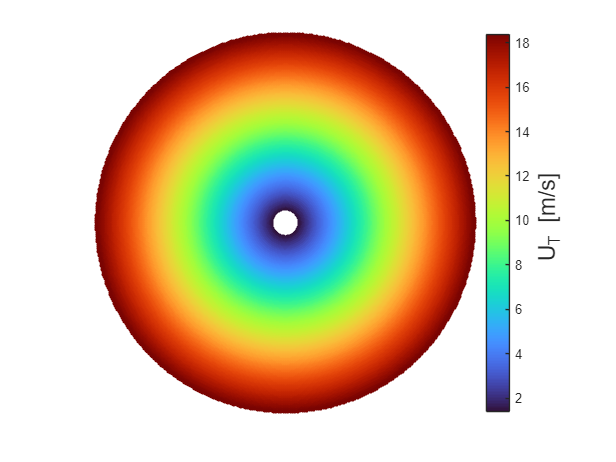

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).U_T;
end
polarPlot(azimutes, rho, values, "", " U_T [m/s]", "./studies/rotor_analysis/sim_B/plots/U_T.eps")

#### Velocidade Radial

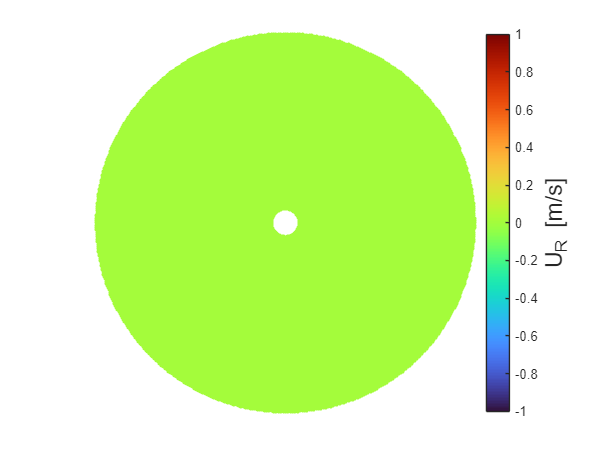

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).U_R;
end
polarPlot(azimutes, rho, values, "", "U_R [m/s]", "./studies/rotor_analysis/sim_B/plots/U_R.eps")

#### Velocidade Vertical

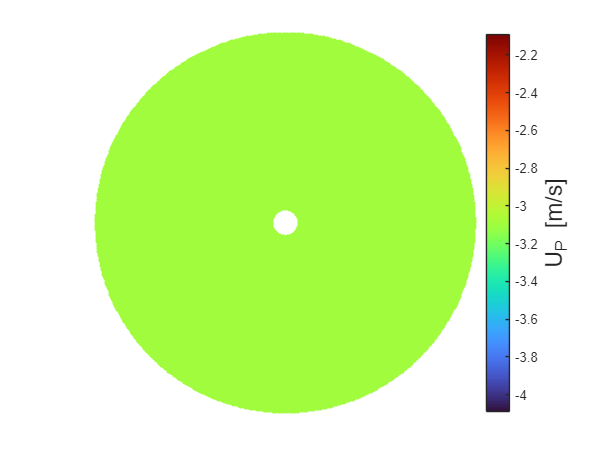

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).U_P;
end
polarPlot(azimutes, rho, values, "", "U_P [m/s]", "./studies/rotor_analysis/sim_B/plots/U_P.eps")

#### Módulo da velocidade 

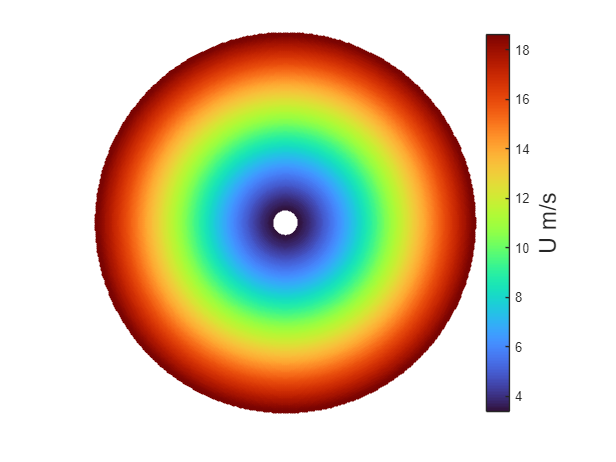

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).total_velocity;
end
polarPlot(azimutes, rho, values, "", "U m/s", "./studies/rotor_analysis/sim_B/plots/total_velocity.eps")

#### Modo de escoamento

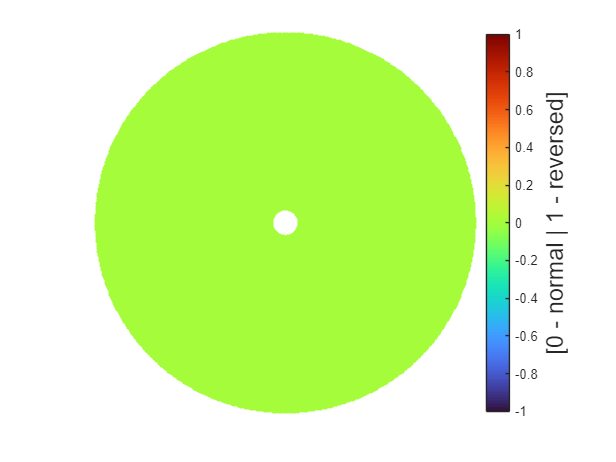

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).flow_mode;
end
polarPlot(azimutes, rho, values, "", "[0 - normal | 1 - reversed]", "./studies/rotor_analysis/sim_B/plots/flow_mode.eps")

#### Número de Reynolds

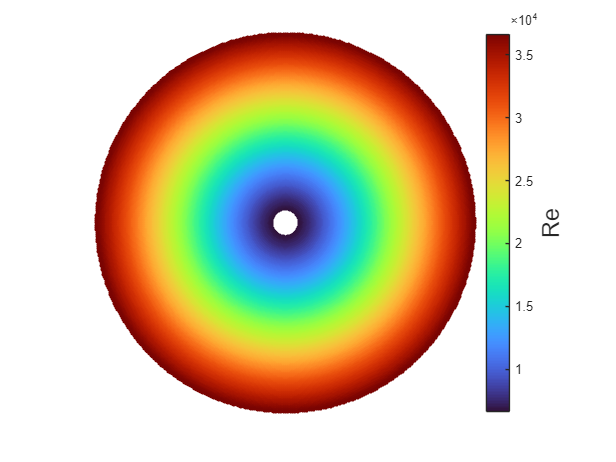

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).Re;
end
polarPlot(azimutes, rho, values, "", "Re", "./studies/rotor_analysis/sim_B/plots/Re.eps")

#### Número de Mach

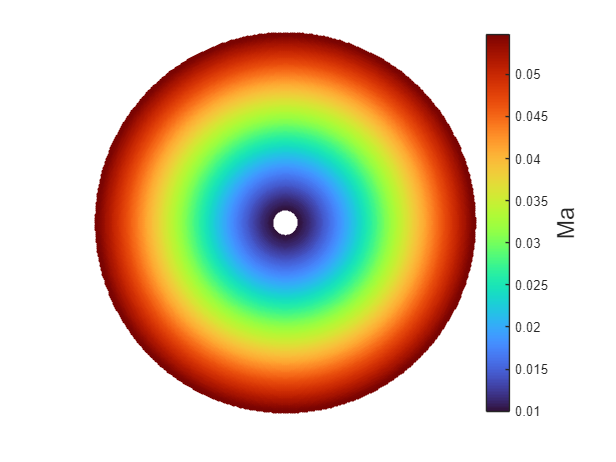

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).Ma;
end
polarPlot(azimutes, rho, values, "", "Ma", "./studies/rotor_analysis/sim_B/plots/mach.eps")

#### Ângulo de picada

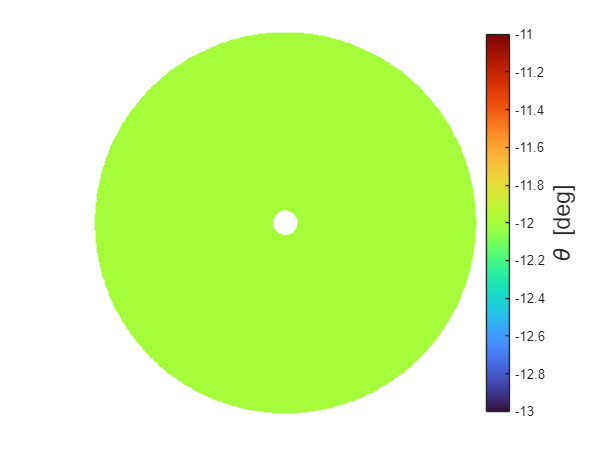

for p=1:length(azimutes)
    values(p, :) = BLADE.theta;
end
polarPlot(azimutes, rho, values, "", "\theta [deg]", "./studies/rotor_analysis/sim_B/plots/theta.eps")

#### Ângulo de incidência

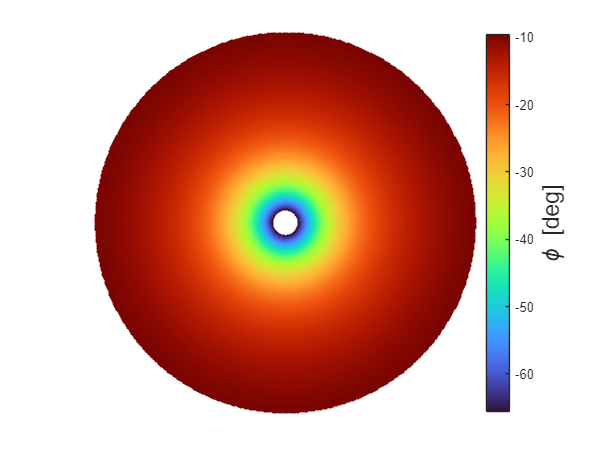

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).phi;
end
polarPlot(azimutes, rho, values, "", "\phi [deg]", "./studies/rotor_analysis/sim_B/plots/phi.eps")

#### Ângulo de ataque

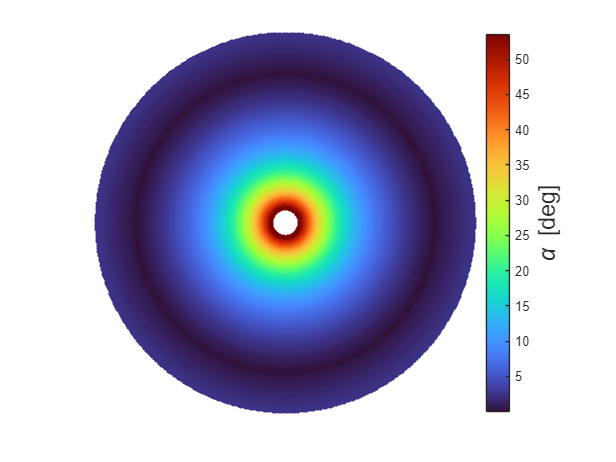

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).alpha;
end
polarPlot(azimutes, rho, values, "", "\alpha [deg]", "./studies/rotor_analysis/sim_B/plots/alpha.eps")

#### Coeficiente de Sustentação

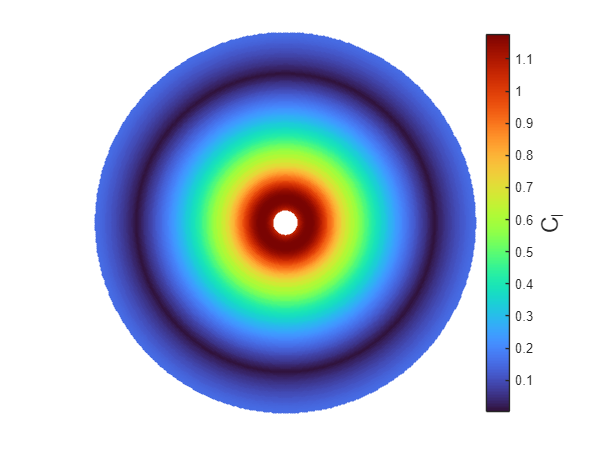

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).Cl;
end
polarPlot(azimutes, rho, values, "", "C_l", "./studies/rotor_analysis/sim_B/plots/cl.eps")

#### Coeficiente de Arrasto

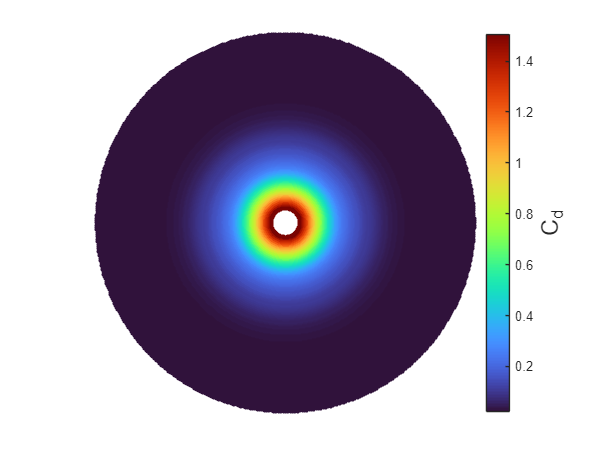

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).Cd;
end
polarPlot(azimutes, rho, values, "", "C_d", "./studies/rotor_analysis/sim_B/plots/cd.eps")

#### Perdas de ponta

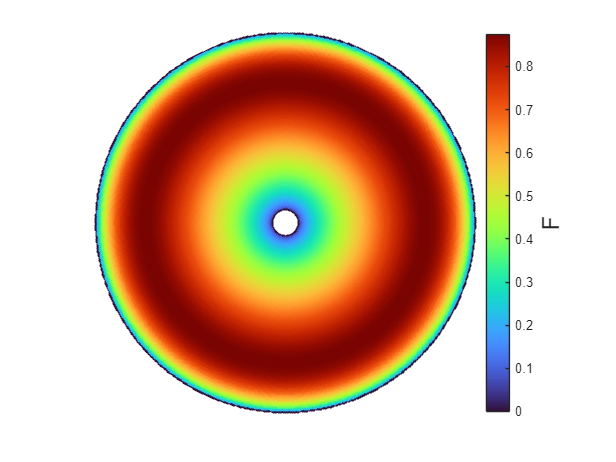

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).f_prandtl;
end
polarPlot(azimutes, rho, values, "", "F", "./studies/rotor_analysis/sim_B/plots/f_prandtl.eps")

#### Força em X - referencial do aerodinâmico

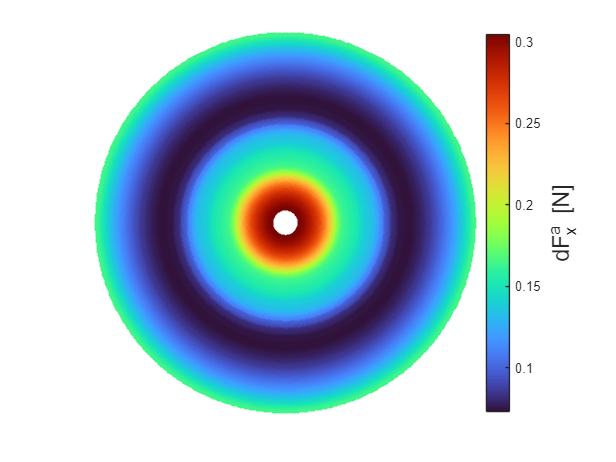

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_a_x;
end
polarPlot(azimutes, rho, values, "", "dF^a_x [N]","./studies/rotor_analysis/sim_B/plots/dFx_a.eps")

#### Força em Y - referencial do aerodinâmico

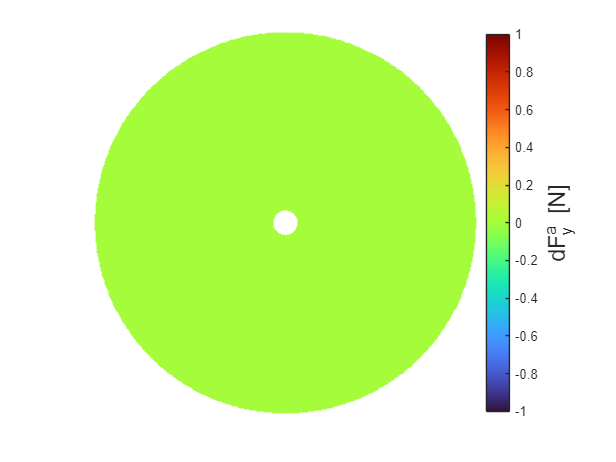

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_a_y;
end
polarPlot(azimutes, rho, values, "", "dF^a_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_a.eps")

#### Força em Z - referencial do aerodinâmico

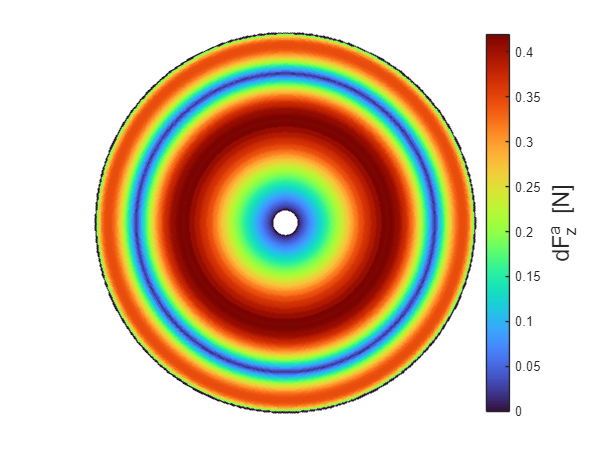

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_a_z;
end
polarPlot(azimutes, rho, values, "", "dF^a_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_a.eps")

#### Força em X - referencial da pá

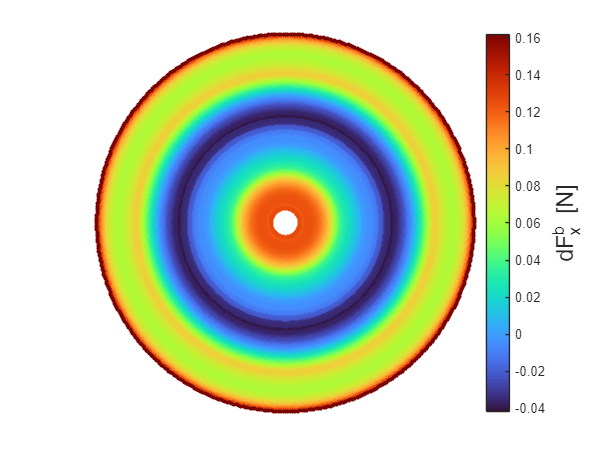

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_e_x;
end
polarPlot(azimutes, rho, values, "", "dF^b_x [N]", "./studies/rotor_analysis/sim_B/plots/dFx_r.eps")

#### Força em Y - referencial da pá

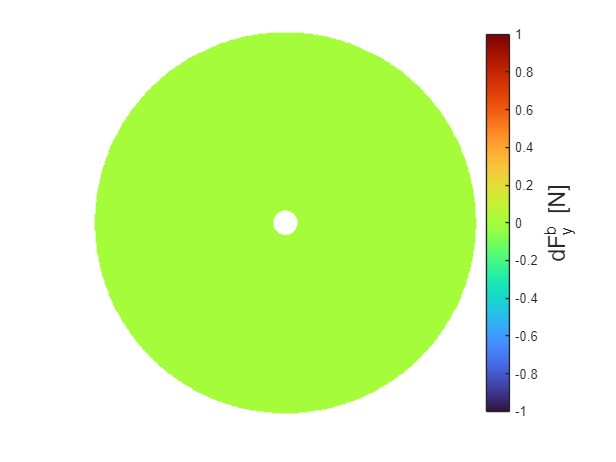

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_e_y;
end
polarPlot(azimutes, rho, values, "", "dF^b_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_r.eps")

#### Força em Z - referencial da pá

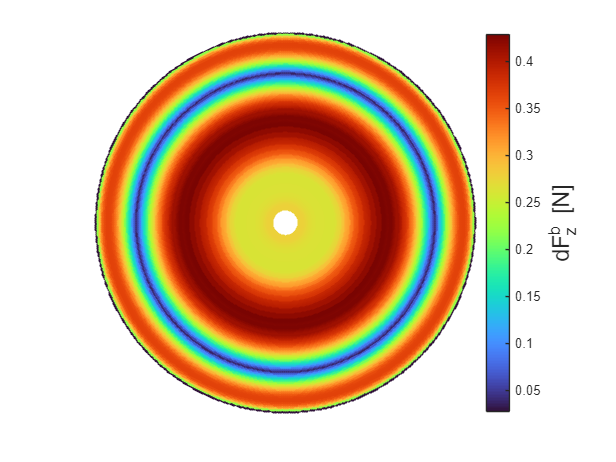

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_e_z;
end
polarPlot(azimutes, rho, values, "", "dF^b_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_r.eps")

#### Força em X - referencial do rotor

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_r_x;
end

Unrecognized method, property, or field 'dF_r_x' for class 'BladeDistribution'.

polarPlot(azimutes, rho, values, "", "dF^r_x [N]", "./studies/rotor_analysis/sim_B/plots/dFx_r.eps")

#### Força em Y - referencial do rotor

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_r_y;
end
polarPlot(azimutes, rho, values, "", "dF^r_y [N]", "./studies/rotor_analysis/sim_B/plots/dFy_r.eps")

#### Força em Z - referencial do rotor

for p=1:length(azimutes)
    values(p, :) = rotor_distribution_data.blade_distribution_data(p).dF_r_z;
end
polarPlot(azimutes, rho, values, "", "dF^r_z [N]", "./studies/rotor_analysis/sim_B/plots/dFz_r.eps")

### Comparação dos integradores

azimutal_points = 100;
array_No_elements = 4 * [1 5 8 10 25 50 100]

#### Rectangle

blade_integrator = 'Rectangle';

f = zeros(1, length(array_No_elements));
t = zeros(1, length(array_No_elements));
for p=1:length(array_No_elements)
    No_elements = array_No_elements(p)
    sim_init_rotor_simulation
    [F_rotor, T_rotor, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
    f_rec(p) = F_rotor(3);
    t_rec(p) = T_rotor(1);
end

#### Trapezoidal

blade_integrator = 'Trapezoidal';

f = zeros(1, length(array_No_elements));
t = zeros(1, length(array_No_elements));
for p=1:length(array_No_elements)
    No_elements = array_No_elements(p)
    sim_init_rotor_simulation
    [F_rotor, T_rotor, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
    f_trap(p) = F_rotor(3);
    t_trap(p) = T_rotor(1);
end

#### Boole

blade_integrator = 'Boole';

f = zeros(1, length(array_No_elements));
t = zeros(1, length(array_No_elements));
for p=1:length(array_No_elements)
    No_elements = array_No_elements(p)
    sim_init_rotor_simulation
    [F_rotor, T_rotor, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
    f_boole(p) = F_rotor(3);
    t_boole(p) = T_rotor(1);
end

#### Simpson

blade_integrator = 'Simpson';

f = zeros(1, length(array_No_elements));
t = zeros(1, length(array_No_elements));
for p=1:length(array_No_elements)
    No_elements = array_No_elements(p)
    sim_init_rotor_simulation
    [F_rotor, T_rotor, ~] = compute_rotor_force(SIM, VEHICLE, ROTOR, BLADE, ATMOSPHERE);
    f_simp(p) = F_rotor(3);
    t_simp(p) = T_rotor(1);
end

#### Figura dos erros


figure()
plot(array_No_elements, f_rec, '-o', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Rectangle')
hold on
plot(array_No_elements, f_trap, '-s', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Trapezoidal')
plot(array_No_elements, f_boole, '-d', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Boole')
plot(array_No_elements, f_simp, '-^', 'LineWidth', 1.5, 'MarkerSize', 6, 'DisplayName', 'Simpson')
hold off

% Melhorias visuais
grid on
box on
xlabel('Number of Elements') % Rótulo do eixo X
ylabel('Force [N]') % Rótulo do eixo Y
title('Comparison of Numerical Integration Methods') % Título do gráfico

% Posiciona a legenda fora do gráfico no canto superior direito
legend('Location', 'northeastoutside')